clc
clear all
close all
pause('off')

# Assignment 4

# Japnit Sethi

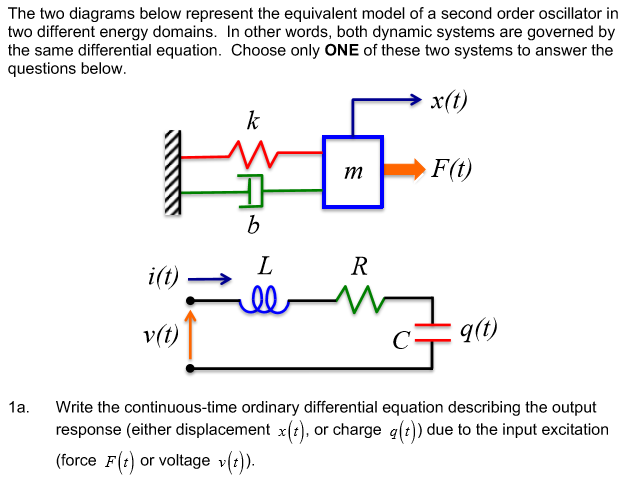

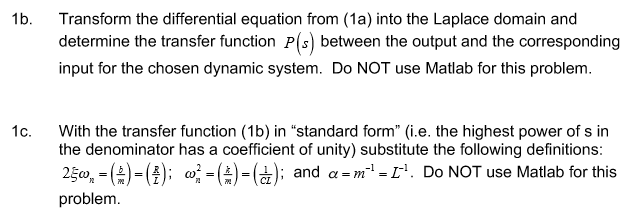

## **Solution:**

Using the mass-spring-damper system with external force, we get a 2nd order linear ode:

$m\ldotp \ddot{x\;} +\;b\ldotp \dot{x} +\;k\ldotp x\;=F$(t)

Laplace transformation:

(m.$s^2$ + b.s + k).x(s) = F(s)

Substituting the definitions:

$\frac{x\left(s\right)}{F\left(s\right)}$ = $\frac{1}{m\ldotp s^2 +b\ldotp s+k}$   $\Longrightarrow$   $\frac{\alpha }{s^2 +2\ldotp \xi \ldotp \omega_n \ldotp s+{\omega_n }^2 }$

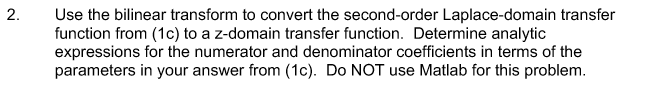

## **Solution:**

Converting from Laplace Domain to z-domain:

We know the Tustin Approximation

s = $\frac{2\ldotp \left(z-1\right)}{T_s \ldotp \left(z+1\right)}$

Transfer Function H(z) simplifies to:

H(z) = $\frac{y\left(z\right)}{u\left(z\right)}$ = $\frac{\alpha }{{\left(\frac{2\ldotp \left(z-1\right)}{T_s \ldotp \left(z+1\right)}\right)}^2 +2\ldotp \xi \ldotp \omega_n \ldotp \frac{2\ldotp \left(z-1\right)}{T_s \ldotp \left(z+1\right)}+{\omega_n }^2 }$   $\Longrightarrow$  $\frac{\alpha \ldotp {T_s }^2 {\left(z+1\right)}^2 }{4\ldotp {\left(z-1\right)}^2 +4\ldotp \xi \ldotp \omega_n \ldotp \left(z^2 -1\right)T_s +{\omega_n }^2 \ldotp {T_s }^2 {\left(z+1\right)}^2 }$  $\Longrightarrow$ $\frac{{\alpha \ldotp {T_s }^2 \ldotp z}^2 +2\alpha \ldotp {T_s }^2 z+\alpha \ldotp {T_s }^2 }{4\ldotp z^2 +4-8z+4\ldotp \xi \ldotp \omega_n \ldotp T_s z^2 \;-4\ldotp \xi \ldotp \omega_n \ldotp T_s +{\omega_n }^2 \ldotp {T_s }^2 z^2 +{\omega_n }^2 \ldotp {T_s }^2 +{{2\ldotp \omega }_n }^2 \ldotp {T_s }^2 \ldotp z\;}$

 $\frac{y\left(z\right)}{u\left(z\right)}$  = $\frac{{\alpha \ldotp {T_s }^2 \ldotp z}^2 +2\alpha \ldotp {T_s }^2 z+\alpha \ldotp {T_s }^2 }{\left(4+4\ldotp \xi \ldotp \omega_n \ldotp T_s +{\omega_n }^2 \ldotp {T_s }^2 \right)\ldotp z^2 +\left({{2\ldotp \omega }_n }^2 \ldotp {T_s }^2 -8\right)z\;+\left(4-4\ldotp \xi \ldotp \omega_n \ldotp T_s +{\omega_n }^2 \ldotp {T_s }^2 \right)\;}$

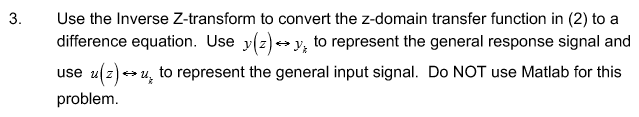

## **Solution:**

Backward Euler Derivative-

$\dot{x} \approx \frac{\delta x}{\delta t}$   = $\frac{x_k -x_{k-1} }{T_S }$

$m\ldotp \frac{\delta \left(\dot{x_k } \right)}{\delta t}+\;b\ldotp \dot{x_k } +\;k\ldotp x_k \;=F_K$  $\Longrightarrow$  $m\ldotp \frac{\delta \left(\frac{x_k -x_{k-1} }{T_S }\right)}{\delta t}+\;b\ldotp \left(\frac{x_k -x_{k-1} }{T_S }\right)+\;k\ldotp x_k \;=F_K$  $\Longrightarrow$   $\frac{m}{T_S }\ldotp$$\frac{\delta \left(x_k \right)}{\delta t}$ - $\frac{m}{T_S }\ldotp$$\frac{\delta \left(x_{k-1} \right)}{\delta t}$ +   $\frac{b}{T_S }\ldotp x_k$ - $\frac{b}{T_S }\ldotp x_{k-1}$ + $k\ldotp x_k \;=F_K$

$\frac{m}{T_S }\ldotp$$\left(\frac{x_k -x_{k-1} }{T_S }\right)$ - $\frac{m}{T_S }\ldotp$$\left(\frac{x_{k-1} -x_{k-2} \;}{T_S }\right)$ +   $\frac{b}{T_S }\ldotp x_k$ - $\frac{b}{T_S }\ldotp x_{k-1}$ + $k\ldotp x_k \;=F_K$  $\Longrightarrow$ $\frac{m}{{T_S }^2 }\ldotp$$x_k$ -  $\frac{m}{{T_S }^2 }\ldotp$$x_{k-1}$ - $\frac{m}{{T_S }^2 }\ldotp$$x_{k-1}$ + $\frac{m}{{T_S }^2 }\ldotp$$x_{k-2}$ +   $\frac{b}{T_S }\ldotp x_k$ - $\frac{b}{T_S }\ldotp x_{k-1}$ + $k\ldotp x_k \;=F_K$

($\frac{m}{{T_S }^2 }$ + $\frac{b}{T_S }\;+k$).$x_k$  -  ($\frac{2m}{{T_S }^2 }$ + $\frac{b}{T_S }$).$x_{k-1}$ + $\frac{m}{{T_S }^2 }\ldotp$$x_{k-2}$  = $F_K$

Can aslo write as:

($\frac{m}{{T_S }^2 }$ + $\frac{b}{T_S }\;+k$).$y_k$  -  ($\frac{2m}{{T_S }^2 }$ + $\frac{b}{T_S }$).$y_{k-1}$ + $\frac{m}{{T_S }^2 }\ldotp$$y_{k-2}$  = $u_K$

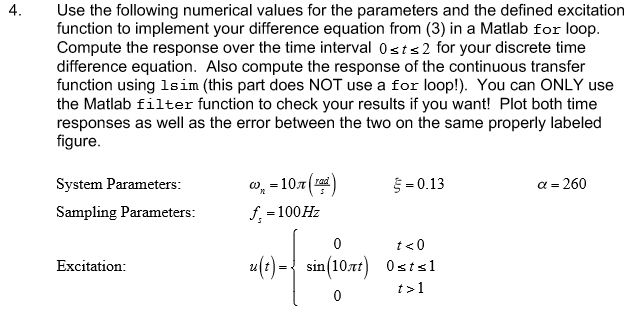

$\frac{x\left(s\right)}{F\left(s\right)}$ = $\frac{1}{m\ldotp s^2 +b\ldotp s+k}$   $\Longrightarrow$   $\frac{\alpha }{s^2 +2\ldotp \xi \ldotp \omega_n \ldotp s+{\omega_n }^2 }$

% Problem 4

fs = 100;   Ts = 1/fs;

tstop = 1;   tfinal = 2;

N = round(tfinal/Ts);

t = Ts * [0:N-1];

u = sin(10*pi*t);
k = find(t <= tstop);
u(k) = zeros(size(k));

yd = zeros(1, N);

for k = 1:N
    if k == 1
        yd(k) = b2*u(k);
    elseif k ==2
        yd(k) = -a1*yd(k-1) + b2*u(k) + b1*u(k-1);
    else
        yd(k) = -a1*yd(k-1) -a0*yd(k-2) + b2*u(k) + b1*u(k-1) + b0*u(k-1);
    end
end

Unrecognized function or variable 'b2'.

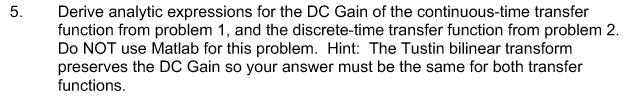

## **Solution:**

**Given**: $\omega_n \;$ = 10.$\Pi$ (rad/s),    $\xi =0\ldotp 13$,    $\alpha$ = 260,        $F\left(t\right)$ = u(t)  = sin(10$\Pi$t)    

{Note: Laplace transform of sin(10$\Pi$t) is $\frac{10\ldotp \Pi }{s^2 +100\ldotp \Pi^2 }$}

2.$\xi$.$\omega_n \;$=  $\frac{b}{m}$  =  2.6$\Pi$ (rad/s),       ${\omega_n }^2$ = $\frac{k}{m}$ = 100.$\Pi^2$ ${\left(\textrm{rad}\right.}^2$/$\left.s^2 \right)$,     $\alpha$ = $m^{-1}$ = 260

Therefore, m = 0.0038,   b = 0.031,   k = 3.75

Continous ODE: 

$m\ldotp \ddot{x\;} +\;b\ldotp \dot{x} +\;k\ldotp x\;=F$(t) 

$\frac{x\left(s\right)}{F\left(s\right)}$ = $\frac{\alpha \ldotp \left(\frac{10\ldotp \Pi }{s^2 +100\ldotp \Pi^2 }\right)}{s^2 +2\ldotp \xi \ldotp \omega_n \ldotp s+{\omega_n }^2 }$     $\Longrightarrow$  $\frac{260\ldotp \left(\frac{10\ldotp \Pi }{s^2 +100\ldotp \Pi^2 }\right)}{s^2 +\left(2\ldotp 6\Pi \right)\ldotp s+\left(100\ldotp \Pi^2 \right)}$

For DC Gain, plug in s = 0   $\Longrightarrow$  $\frac{260}{\left(100\ldotp \Pi^2 \right)}\ldotp \left(\frac{1}{10\Pi }\right)$ $\Longrightarrow$ DC Gain is 8.39*${10}^{-4}$

Tustin Transformation


$$\left(\frac{10\ldotp \Pi }{s^2 +100\ldotp \Pi^2 }\right)$$
 
$$\Longrightarrow$$
 
$$\left(\frac{10\ldotp \Pi }{{\left(\frac{2\ldotp \left(z-1\right)}{T_s \ldotp \left(z+1\right)}\right)}^2 +100\ldotp \Pi^2 }\right)$$


For DC Gain, plug in z = 1

$\frac{y\left(z\right)}{u\left(z\right)}$ = $\frac{\alpha \ldotp \left(\frac{10\ldotp \Pi }{{\left(\frac{2\ldotp \left(z-1\right)}{T_s \ldotp \left(z+1\right)}\right)}^2 +100\ldotp \Pi^2 }\right)}{{\left(\frac{2\ldotp \left(z-1\right)}{T_s \ldotp \left(z+1\right)}\right)}^2 +2\ldotp \xi \ldotp \omega_n \ldotp \frac{2\ldotp \left(z-1\right)}{T_s \ldotp \left(z+1\right)}+{\omega_n }^2 }$

DC Gain = $\frac{\alpha \ldotp \left(\frac{1}{10\Pi }\right)}{{\omega_n }^2 }$ = $\frac{260}{\left(100\ldotp \Pi^2 \right)}\ldotp \left(\frac{1}{10\Pi }\right)$ $\Longrightarrow$ DC Gain is 8.39*${10}^{-4}$